## Titre def plus hypo

Dans cette section, nous discuté des choix et des hypothèses que nous avons définie pour la modélisation du sousmarin.

### Hypothèse

Afin de mieux nous guider dans la modélisation de notre sous-marin, nous avons faite deux suppositions afin d'alléger l'équation dynamique. 

Premièrement, notre sous-marin possède une grande rigidité en raison de ses parois en aluminium qui possède une épaisseur allant jusqu'à 10mm. De plus, nos vitesses sont relativement faibles soit autour de 1m/s. Nous pouvons donc supposer que les déformations dimensionnelles sous l'effet des forces externes sont négligeables. Ceci permet de définir notre sous-marin comme un corps rigide. 

Deuxièmement, les dimensions du bassin de la compétition ne sont pas très grandes. Les déplacements que le sous-marin effectuera seront relativement faibles soit de 1 à 100m et donc négligeables par rapport à la courbure de la terre. Nous pouvons donc présumer que la terre est plate. Ceci va nous permettre d'utiliser un référentiel cartésien (X Y Z) et non le référentiel de la terre (longitude latitude altitude).

### Définition du référentiel.

Dans le livre *Guidance and Control of Ocean Vehicules, *Thor I. Fossen (1994) suggère d'utiliser deux référentiels distincts lorsque nous voulons faire l'analyse dynamique d'un véhicule nautique en 6 dégrées de libertés (DDL). La figure suivante montre bien les deux référentiels que nous allons utiliser. 

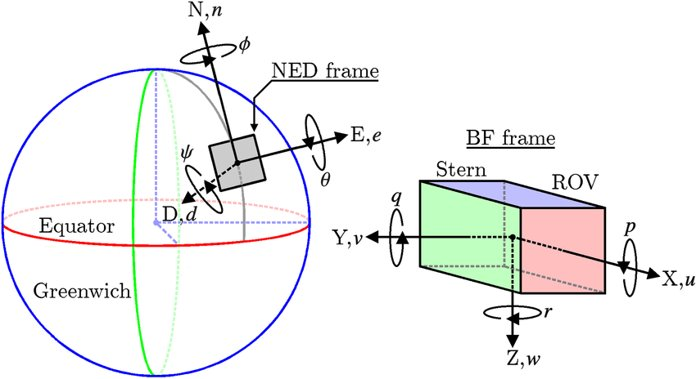

Path Generation for High-Performance Motion of ROVs Based on a Reference Model - Scientific Figure on ResearchGate. Available from: https://www.researchgate.net/figure/NED-and-BF-reference-frames_fig2_277013046 [accessed 26 Jan, 2021]�

Vu que nous supposons que la terre est plate, nous pouvons crée un plan tangent sur la surface de la Terre dépendamment de notre position et de le considérer pour crée un référentiel cartésien fixe. C'est pour cette raison qu'il est important de calibrer notre IMU lorsque nous allons en compétition. Nous pouvons aussi considérer ce référentiel comme étant inertiel. Nous avons décidé d'utiliser la convention « NED » pour « North East Down » de façon que les axes aient la configuration suivante:

- X+ : le nord

- Y+ : l'est

- Z+ : le bas

Le référentiel mobile couramment appelé BF pour « Body Fixed » est un référentiel qui suit le sous-marin durant ces déplacements. Pour les véhicules mobiles, il est recommandé de placer l'origine de référentiel au centre de masse et que les axes aient la configuration suivante:

- X : l'axe longitudinal 

- Y : l'axe transversal

- Z : l'Axe normal 

Étant donné que notre référentiel fixe est considéré comme étant inertiel, il est possible de définir la dynamique du référentiel « BF » selon le référentiel fixe. Avec les suppositions que nous venons de définir, dans le livre *Guidance and Control of Ocean Vehicules, *Thor I. Fossen (1994) recommande donc de définir la position et l'orientation en fonction référentielle inertiel ainsi que les vitesses linéaire et angulaire en fonction du référentiel « BF ».

### Définition de la représentation de l'orientation

Pour représenter l'orientation du sous-marin, nous avons décidé d'opter pour le quaternion unitaire au lieu des angles d'Euler autant pour des raisons mathématiques que pour des raisons d'implémentation. Même si le quaternion n'est pas aussi intuitif que les angles d'Euler, il possède de gros avantages qui expliquent sa popularité. Afin de concorder avec matlab, nous avons décider d'utiliser la convention ou la partie scalaire ce trouve au début et que la partie imaginaire seconde. Soit:


$$q=\eta +\varepsilon_1 \;\mathit{\mathbf{i}}+\varepsilon_2 \;\mathit{\mathbf{j}}+\varepsilon_1 \;\mathit{\mathbf{k}}$$


D'un point de vue mathématique, vu que le quaternion possède quatre paramètres au lieu de trois, il est en mesure de définir n'importes qu'elles rotation en évitant toute singularité. Ce phénomène est plus connu sous le nom de « Gimbal lock ». De plus, le quaternion ne contient pas de discontinué. Avec les angles d'Euler, ce problème est plus connu sous « wraparound » et nous pouvons retrouver ce problème lorsque qu'un angle approche $\pm \pi$radian  . la figure suivante montre ce phénomène.

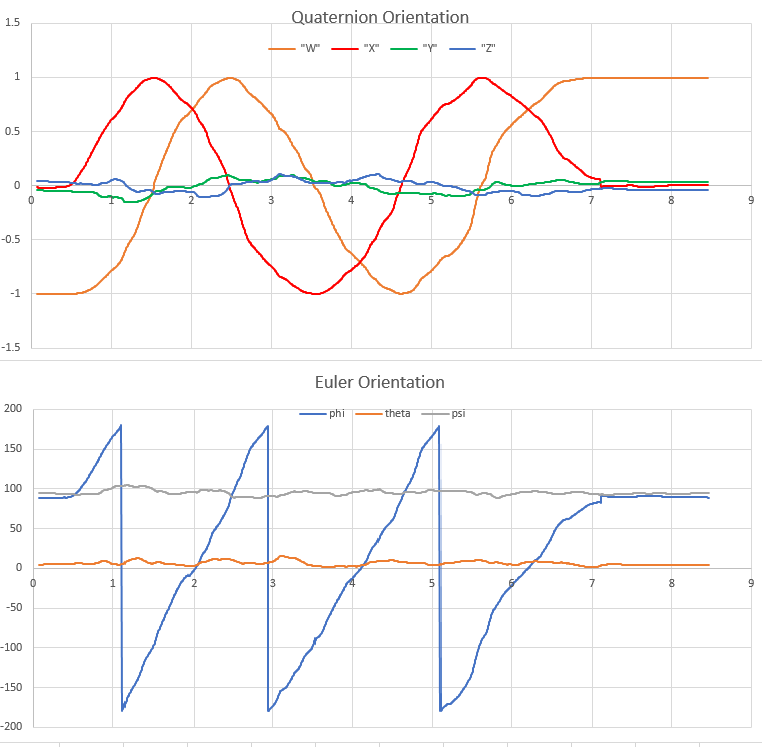

[https://blog.endaq.com/quaternions-for-orientation](https://blog.endaq.com/quaternions-for-orientation)

En ce qui concerne l'implémentation de notre modèle, nous avons avantage à utiliser le quaternion, car il est plus stable numériquement. Ceci explique sa grande popularité dans les applications numériques. La preuve, les logiciels que nous utilisons (ROS Gazebo Unity) utilisent tous le quaternion. Ce pourquoi nous avons intérêt à utiliser le quaternion.

Cependant, définir le modèle physique en quaternion n'oblige pas pour autant que la commande doit l'utiliser aussi.

### Définition des variables

Dans cette section nous allons définir les variables qui vons nous être utiles pour la modélisaton. Pour etre le plus cohérents possible avec le livre *Guidance and Control of Ocean Vehicules, *Thor I. Fossen (1994), Nous allons utiliser la même notation que le livre, soit celle  définie par SNAME(1950).

### Variables pour les degrées de libertés (DDL)

Le tableau suivant utilise la notation définie par SNAME(1950).

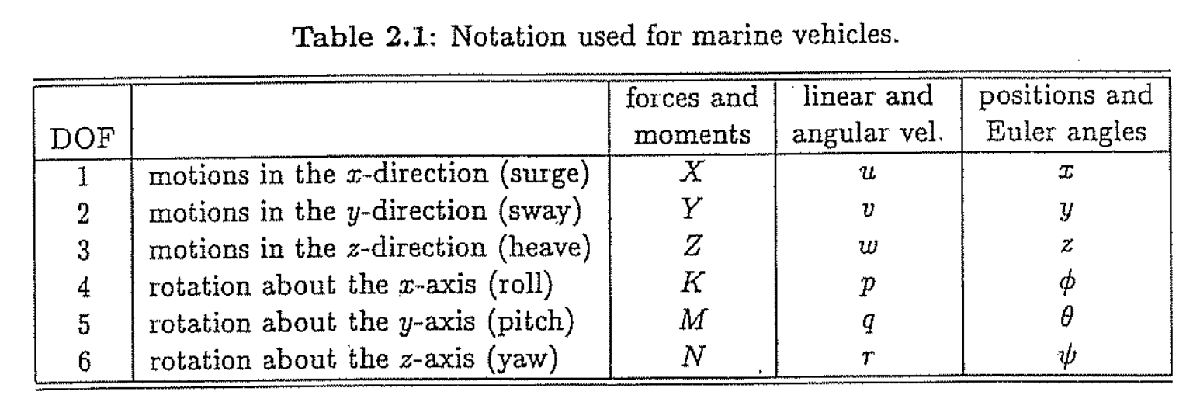

Même si nous comptons utiliser le quaternions, nous allons quand même définir les angles d'euler à des fin d'analyse

clear;
sympref('MatrixWithSquareBrackets',true)

ans = logical
   1


   
% Définir les forces et moments
    syms X Y Z K M N
    syms Fm
    syms tauE
    
% Définir les vitesses linéaires et angulaires
    syms u v w p q r

% Définir les positions linéaires
    syms x y z
    
% Définir les angle d'euler
    syms phi theta psi
    
% Définir la partie scalaire du quaternion
    syms eta;
        
% Définir la partie vectorielle du quaternion
    syms('epsilon',[3,1]);
    
% Définir le quaternion  
        e=[eta; epsilon]; 
        
% Définir les entrées système (Thruster)
    syms ('U',[8,1])

% Définir les forces externes et perturbations
    syms ('F_ext',[6,1])
    
% Condition Initials
    syms ('Ne_0',[7,1])
    syms ('N_0',[6,1])
    syms ('V_0',[6,1])
    
% Variable de perturbation
    syms ('Delta_Ne',[7,1])
    syms ('Delta_V',[6,1])
    
    disp(Delta_Ne)

$$\left[\begin{array}{c} \Delta_{\mathrm{Ne1}}\\ \Delta_{\mathrm{Ne2}}\\ \Delta_{\mathrm{Ne3}}\\ \Delta_{\mathrm{Ne4}}\\ \Delta_{\mathrm{Ne5}}\\ \Delta_{\mathrm{Ne6}}\\ \Delta_{\mathrm{Ne7}} \end{array}\right]$$

### Regroupement des variables

Nous allons par la suite regrouper les variables sous la forme vectoriel en utilisant le formalisme suivant.

### 
$$\;v\;=\left\lbrack v_1^T ,v_2^T \right\rbrack \;;\;\;\;\;\;\;\;{\;v}_1 ={\left\lbrack u,v,w\right\rbrack }^T ;\;\;\;\;\;\;v_2 ={\left\lbrack p,q,r\right\rbrack }^T ;\;\;$$


### 
$$n_e =\left\lbrack n_1^T ,n_2^T \right\rbrack \;;\;\;\;\;\;\;\;n_1 ={\left\lbrack x,y,z\right\rbrack }^T ;\;\;\;\;\;\;\;n_2 ={\left\lbrack \phi ,\theta ,\psi \right\rbrack }^T ;\;\;$$
  

### 
$$n_q =\left\lbrack n_1^T ,e^T \right\rbrack \;;\;\;\;\;\;\;\;n_1 ={\left\lbrack x,y,z\right\rbrack }^T ;\;\;\;\;\;\;\;\;\;e={\left\lbrack \eta ,\;\varepsilon_1 ,\;\varepsilon_2 ,{\;\varepsilon }_3 \right\rbrack }^T ;\;\;$$
  

% Position et Orientation 
    n1 = [x,y,z].';
    n2 = [phi, theta, psi].';
    
    Ne = [n1;n2];
    Nq =[n1;e];
    
% Vitesses
    v1=[u,v,w].';
    v2=[p,q,r].';
    V=[v1;v2]

$$V = \left[\begin{array}{c} u\\ v\\ w\\ p\\ q\\ r \end{array}\right]$$

    
% Forces et moments
   Fm=[X,Y,Z,K,M,N].';

% Perturbation + initial
  NODN =N_0+V_0

$$NODN = \left[\begin{array}{c} N_{01}+V_{01}\\ N_{02}+V_{02}\\ N_{03}+V_{03}\\ N_{04}+V_{04}\\ N_{05}+V_{05}\\ N_{06}+V_{06} \end{array}\right]$$

### Constante du modèle physique

Dans cette section nous allons définire les constantes mécaniques qui vont nous être utiles pour la modélisation du sous-marin

% distance truster x y z selon centre geommétrique (Constantes)
% D14 distance thruster 1 a 4. (Constantes)
% D58 distance thruster 5 a 8. (Constantes)
% a14 angle thruster 1 a 4. (Constantes)
% dz distance entre les increments sur le frame. (Constantes)
% PZ position des truster sur le frame. (Constantes)
    syms('D14',[1 3]); syms('D58',[1 3]) ; syms a14 dz ; syms ('PZ',[1,4]);

% masse, volume du prototype et hauteur sub (Constantes)
    syms mass volume height

% coefficient de drag (Constantes)
    syms ('CD_L',[1, 6])    % Lineaire
    syms ('CD_Q', [1, 6]);  % Quadratique

% aire de surface du sub (Constantes)
    syms ('AF', [1, 3]);

% matrice d'inertie (Constantes)
    syms ('I', [3, 3]);

% centre de gravité RG et centre de flotataison RB (Constantes)
    syms ('RG',[3 1]); syms('RB',[3 1])
    
% Constantes physique (densité de leau et accélération gravitationel)
    syms rho g
    
% Constance Mecanique
   constMec = [D14 D58 a14 dz PZ mass volume height AF...
             I(1,:) I(2,:) I(3,:) RG.' RB.' CD_L CD_Q rho g];


## Équation cinématique du mouvement 

Dans cette section, nous allons définire l'équation différentielle de la cinématique du sous marin. Cette équation transforme les vitesses linéaire et angulaire du référentiel objet au référentiel inertiel.  De plus, les vitesse angulaire seront transformer afin de pouvoir être intégré dans leur représentation respectif. De cette façon, nous seront en mesure de déterminer la position et l'orientation du sous-marin par rapport au référentiel fixe. Cette section est importantes, car tous les capteur sur le sous-marin donnes leurs valeur dans le référentiel objet . Il nous est donc impossible de mesurer les états du sous-marin directement à partir du rérérentiel fixe. La figure suivante montre la relation entre les varible lié au référentiel objet et ceux du référentiel fixe.

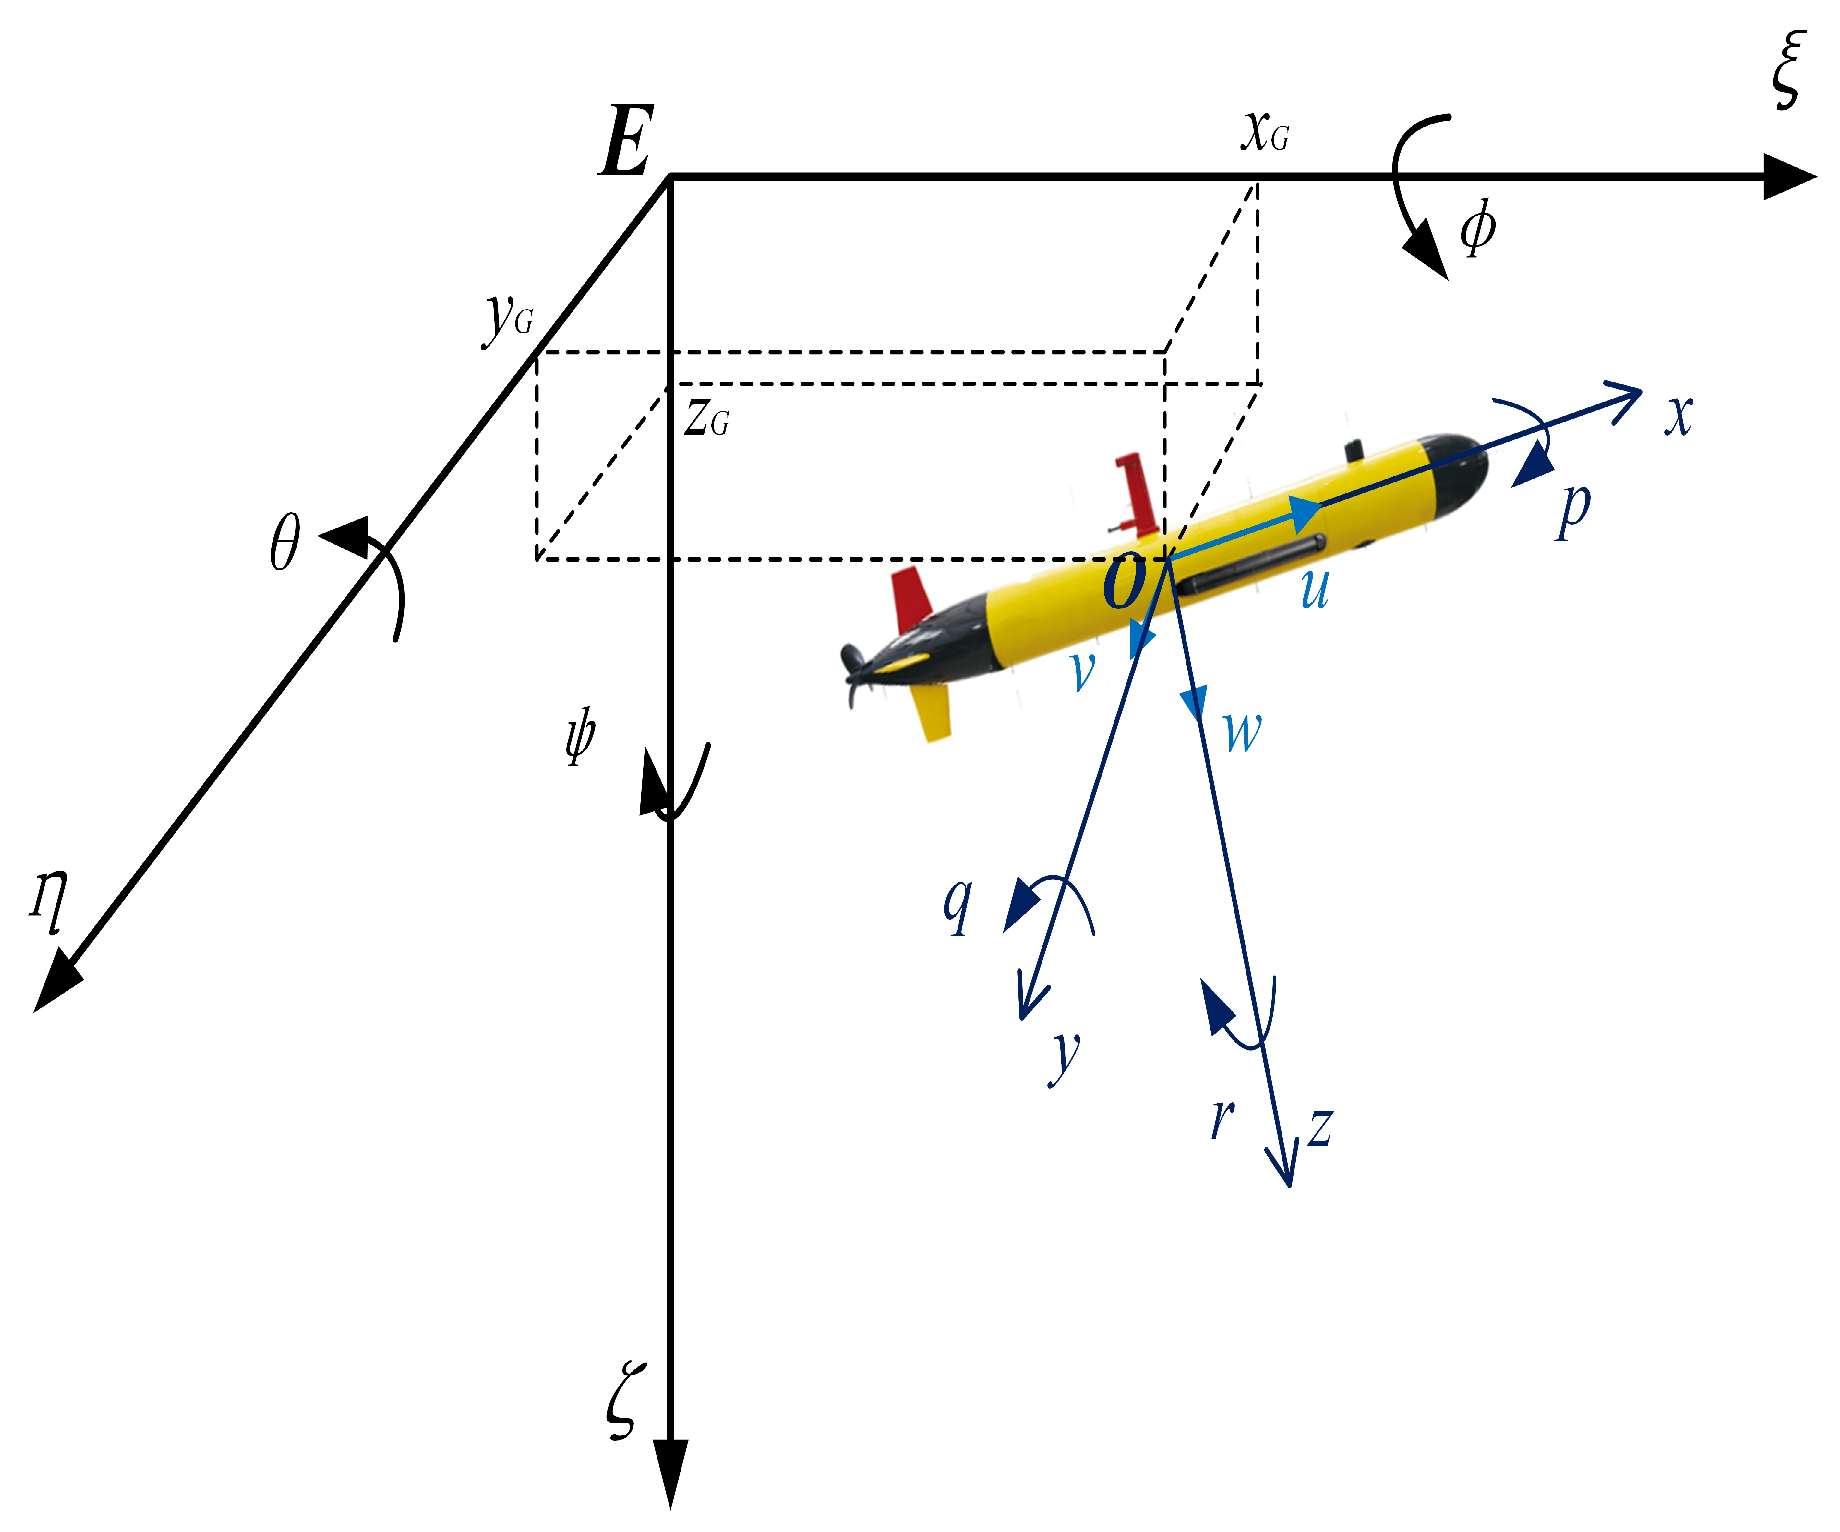

https://www.mdpi.com/2076-3417/9/17/3518/htm#B31-applsci-09-03518

Nous allons commencer par définir l'équation cinématique avec la représentation d'angle d'Euler, car la plupart des concepts utilisés sont abordés dans le cours GPA546. Il sera donc plus facile de comprendre l'idée derrière ce concept avant de construire la même équation cinématique, mais en utilisant les quaternions.

## Équation cinématique du mouvement (Euler)

Dans cette section nous allons définir une autre équation cinématique, mais cette fois-ci en utilisant les angle d'Euler. Dans cette section, nous allons utiliser l'orde de rotation ZYX. L'équation différentiel va avoir la même forme que pour le quaternion, sauf que les dimentions et les équation diffèrent un peu. Ce qui donne :


$${\dot{n} }_e =J\left(n_e \right)v\;\iff \left\lbrack \begin{array}{c}
{\dot{n} }_1 \\
{\dot{n} }_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
J_1 \left(n_2 \right) & 0_{3\textrm{x3}} \\
0_{3\textrm{x3}}  & J_2 \left(n_2 \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_1 \\
v_2 
\end{array}\right\rbrack \;{\;\in \Re }^6$$


Afin d'allèger l'écriture des matrices, nous allons utiliser la notation « c » pour le cosinus, « s » pour le sinus et « t » pour la tangente.

#### Transformation de la vitesse linéaire

Dans cette section, nous allons déterminer la transformation de la vitesse linéaire, soit la matrice $J_1$. Dans un premier temps, il faut définir les matrice de rotation de base pour chaques axes de rotation.


$$R_{x,\phi } =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & c\left(\phi \right) & s\left(\phi \right)\\
0 & -s\left(\phi \right) & c\left(\phi \right)
\end{array}\right\rbrack \;\;$$
   
$$R_{y,\theta } =\left\lbrack \begin{array}{ccc}
c\left(\theta \right) & 0 & -s\left(\theta \right)\\
0 & 1 & 0\\
s\left(\theta \right) & 0 & c\left(\theta \right)
\end{array}\right\rbrack$$
     
$$R_{z,\psi } =\left\lbrack \begin{array}{ccc}
c\left(\psi \right) & s\left(\psi \right) & 0\\
-s\left(\psi \right) & c\left(\psi \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


% Angle Euler Z Y X
    Rz = [ cos(psi), sin(psi), 0;
           -sin(psi),  cos(psi), 0;
           0        ,  0        , 1];
       
    Ry = [ cos(theta), 0,  -sin(theta);
           0          , 1,  0;
          sin(theta), 0,  cos(theta)];
      
    Rx = [1, 0        , 0;
          0, cos(phi), sin(phi);
          0, -sin(phi), cos(phi)];

Maintenant, si nous voullons la matrice de rotation qui suit l'orde ZYX, il suffit de multiplier les transposés des matices de rotation de base dans le même orde. Il faut ce rappeler que le produit des matrice de rotation n'est pas commutative. L'orde est donc très important. Ce qui donne:


$$J_1 \left(n_2 \right)={R_{z,\psi } }^T {R_{y,\theta } }^T {R_{x,\phi } }^T$$


Nous pouvons déveloper cette équation, ce qui nous donne:


$$J_1 \left(n_2 \right)=\left\lbrack \begin{array}{ccc}
c\left(\psi \right)\,c\left(\theta \right) & c\left(\psi \right)\,s\left(\phi \right)\,s\left(\theta \right)-c\left(\phi \right)\,s\left(\psi \right) & s\left(\phi \right)\,s\left(\psi \right)+c\left(\phi \right)\,c\left(\psi \right)\,s\left(\theta \right)\\
c\left(\theta \right)\,s\left(\psi \right) & c\left(\phi \right)\,c\left(\psi \right)+s\left(\phi \right)\,s\left(\psi \right)\,s\left(\theta \right) & c\left(\phi \right)\,s\left(\psi \right)\,s\left(\theta \right)-c\left(\psi \right)\,s\left(\phi \right)\\
-s\left(\theta \right) & c\left(\theta \right)\,s\left(\phi \right) & c\left(\phi \right)\,c\left(\theta \right)
\end{array}\right\rbrack$$


% Matrice de transformation vitesse liéaire du frame sub au frame world
    J1 = simplify(Rz.' *Ry.' *Rx.');

#### Transformation de la vitesse angulaire

Dans cette section, nous allons définir une relation pour transformer les vitesse angulaire du référentiel objet $v_2 ={\left\lbrack p,q,r\right\rbrack }^T$en vecteur de rotation instantané $\dot{n_2 } ={\left\lbrack \phi^˙ ,\theta^˙ ,\psi^˙ \right\rbrack }^T$. Nous pouvons définier une matrice de transformation $J_2$ pour nous permettre cette transformation. Ce qui donne:


$${\dot{n} }_2 =J_2 \left(n_2 \right){\;v}_2$$


Comparer à des vitesse linéaire, nous ne pouvons directement intégrer les vitesse angulaire $v_2 ={\left\lbrack p,q,r\right\rbrack }^T$ afin d'obtenir son orientation. Cependant il possible d'intégré un vecteur de rotation instantané  $\dot{n_2 } ={\left\lbrack \phi^˙ ,\theta^˙ ,\psi^˙ \right\rbrack }^T$ afin d'obtenir l'orientation du sous-marin dans le référentiel inertiel. Pour effectuer cette  conversion nous pouvons utiliser la relation suivante.

$v_2 =\left\lbrack \begin{array}{c}
\phi^˙ \\
0\\
0
\end{array}\right\rbrack +$$R_{x,\phi }$$\left\lbrack \begin{array}{c}
0\\
\theta^˙ \\
0
\end{array}\right\rbrack$+ $R_{x,\phi }$$R_{y,\theta }$$\left\lbrack \begin{array}{c}
0\\
0\\
\psi^˙ 
\end{array}\right\rbrack =J_2^{-1} \left(n_2 \right){\dot{n} }_2$

Nous pouvons développer cette relation afin de déterminer la matrice $J_2^{-1}$ puis l'inverser pour avoir la matrice $J_2$.


$$J_2^{-1} =\left\lbrack \begin{array}{ccc}
1 & 0 & -s\left(\theta \right)\\
0 & c\left(\phi \right) & c\left(\theta \right)\,s\left(\phi \right)\\
0 & -s\left(\phi \right) & c\left(\phi \right)\,c\left(\theta \right)
\end{array}\right\rbrack \;\;\;\Rightarrow \;\;\;\;J_2 =\left\lbrack \begin{array}{ccc}
1 & \frac{s\left(\phi \right)\,s\left(\theta \right)}{c\left(\theta \right)} & \frac{c\left(\phi \right)\,s\left(\theta \right)}{c\left(\theta \right)}\\
0 & c\left(\phi \right) & -s\left(\phi \right)\\
0 & \frac{s\left(\phi \right)}{c\left(\theta \right)} & \frac{c\left(\phi \right)}{c\left(\theta \right)}
\end{array}\right\rbrack$$


% Calcule de la matrice J2 inverse
    J2inv= [[1,0,0].',Rx*[0,1,0].',Rx*Ry*[0,0,1].'];
% Calcule de la matrice J2
    J2=simplify(inv(J2inv));

#### Matrice de transformation

Nous avons donc tous éléments nécéssaire pour construire notre matrice J. Nous pouvons la développer, ce qui donne le résultat suivant. 


$$J=\left\lbrack \begin{array}{cccccc}
c\left(\psi \right)\,c\left(\theta \right) & c\left(\psi \right)\,s\left(\phi \right)\,s\left(\theta \right)-c\left(\phi \right)\,s\left(\psi \right) & s\left(\phi \right)\,s\left(\psi \right)+c\left(\phi \right)\,c\left(\psi \right)\,s\left(\theta \right) & 0 & 0 & 0\\
c\left(\theta \right)\,s\left(\psi \right) & c\left(\phi \right)\,c\left(\psi \right)+s\left(\phi \right)\,s\left(\psi \right)\,s\left(\theta \right) & c\left(\phi \right)\,s\left(\psi \right)\,s\left(\theta \right)-c\left(\psi \right)\,s\left(\phi \right) & 0 & 0 & 0\\
-s\left(\theta \right) & c\left(\theta \right)\,s\left(\phi \right) & c\left(\phi \right)\,c\left(\theta \right) & 0 & 0 & 0\\
0 & 0 & 0 & 1 & \frac{s\left(\phi \right)\,s\left(\theta \right)}{c\left(\theta \right)} & \frac{c\left(\phi \right)\,s\left(\theta \right)}{c\left(\theta \right)}\\
0 & 0 & 0 & 0 & c\left(\phi \right) & -s\left(\phi \right)\\
0 & 0 & 0 & 0 & \frac{s\left(\phi \right)}{c\left(\theta \right)} & \frac{c\left(\phi \right)}{c\left(\theta \right)}
\end{array}\right\rbrack$$


Nous pouvons remarquer que cette matrice n'est pas défini pour l'ensemble des angles  $\theta \in \left\lbrack -\pi ,\pi \right\rbrack$. En effet, nous pouvons constater que nous avons des divisions par 0 losque l'angle $\theta$(pitch) vaut $\pm \frac{\pi }{2}$radians. Ceci crée alors des zones de singularités. Ceci n'est pas une surprise car toutes les représentations d'orientation à trois paramètres contiens des zone singulière. Cependant,  la plupart des aplications martime ne travail pas autours des zones de singularités que nous avons déterminé. Il est donc possible d'utiliser cette représenation dans notre application. 

% Définir la matrice de transformation J(ne)
    Je=[J1,zeros(3,3);
    zeros(3,3),J2];

### Équation cinématique représenter avec le quaternion unitaire

Dans cette section nous allons définir l'équation cinématique basé sur le quaternion. Nous pouvons exprimer cette équation différentiel sous la forme matriciel suivante.


$${\dot{n} }_q =E\left(n_q \right)v\;\iff \left\lbrack \begin{array}{c}
{\dot{n} }_1 \\
\dot{e} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
E_1 \left(e\right) & 0_{3\textrm{x3}} \\
0_{4\textrm{x3}}  & E_2 \left(e\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
v_1 \\
v_2 
\end{array}\right\rbrack \;{\;\in \Re }^7$$


#### Transformation de la vitesse linéaire

Dans cette section, nous allons déterminer la transformation de la vitesse linéaire. Cette équation prend la forme suivante:


$${\dot{n} } =E_1 \left(e\right){\;v}_1$$


 Nous pouvons transformer un vecteur d'un référentiel à un autre en fonction d'un quaternion décrivant la transformation entre les deux référentiels en utilisant la relation suivante.


$$E_1 =I_{3\mathrm{X3}\;} +2\eta \mathit{\mathbf{S}}\left(\varepsilon \right)+2{\mathit{\mathbf{S}}}^2 \left(\varepsilon \right)$$


Ou $I_{3\textrm{X3}\;}$est une matrice identitaire et **S **est une matrice anti symétrique $\Re^{3\mathrm{x3}}$.

Nous pouvons développer la relation précédente pour l'avoir sous la forme matriciel. 


$$E_1 =\left\lbrack \begin{array}{ccc}
-2\,{\varepsilon_2 }^2 -2\,{\varepsilon_3 }^2 +1 & 2\,\varepsilon_1 \,\varepsilon_2 -2\,\varepsilon_3 \,\eta  & 2\,\varepsilon_1 \,\varepsilon_3 +2\,\varepsilon_2 \,\eta \\
2\,\varepsilon_1 \,\varepsilon_2 +2\,\varepsilon_3 \,\eta  & -2\,{\varepsilon_1 }^2 -2\,{\varepsilon_3 }^2 +1 & 2\,\varepsilon_2 \,\varepsilon_3 -2\,\varepsilon_1 \,\eta \\
2\,\varepsilon_1 \,\varepsilon_3 -2\,\varepsilon_2 \,\eta  & 2\,\varepsilon_2 \,\varepsilon_3 +2\,\varepsilon_1 \,\eta  & -2\,{\varepsilon_1 }^2 -2\,{\varepsilon_2 }^2 +1
\end{array}\right\rbrack$$


% Équation E1
    E1=eye(3)+2*eta*skew(epsilon)+2*skew(epsilon)^2;
    

#### Transformation de la vitesse angulaire

Dans cette section, nous allons définir l'équation de la transformation de la vitesse angulaire, Cette équation prend la forme suivante:


$$\dot{e} =E_2 \left(e\right){\;v}_2$$


 De la même façon que pour les angles d'Euler, nous devons transformé les vitesse angulaire du référentiel objet $v_2 ={\left\lbrack p,q,r\right\rbrack }^T$ en quaternion instantané $\dot{e} =\left\lbrack \eta^˙ \;\;\;{\varepsilon^˙ }_1 \;{\dot{\;\varepsilon } }_2 \;{\varepsilon^˙ }_3 \right\rbrack$  afin d'être en mesure de l'intégré dans le référentiel fixe. Pour effectuer cette conversion, nous pouvons utiliser la relation suivante.


$$E_2 =\frac{1}{2}\left\lbrack \begin{array}{ccc}
-\varepsilon_1  & -\varepsilon_2  & -\varepsilon_3 \\
\eta  & -\varepsilon_3  & \varepsilon_2 \\
\varepsilon_3  & \eta  & -\varepsilon_1 \\
-\varepsilon_2  & \varepsilon_1  & \eta 
\end{array}\right\rbrack$$


% Équation E2
     E2=(1/2)*[-epsilon.';eta*eye(3)+skew(epsilon)];

#### Matrice de transformation

Nous avons donc tous éléments nécéssaire pour construire notre matrice E. Nous pouvons la développer, ce qui donne le résultat suivant. 


$$E=\left\lbrack \begin{array}{cccccc}
-2\,{\varepsilon_2 }^2 -2\,{\varepsilon_3 }^2 +1 & 2\,\varepsilon_1 \,\varepsilon_2 -2\,\varepsilon_3 \,\eta  & 2\,\varepsilon_1 \,\varepsilon_3 +2\,\varepsilon_2 \,\eta  & 0 & 0 & 0\\
2\,\varepsilon_1 \,\varepsilon_2 +2\,\varepsilon_3 \,\eta  & -2\,{\varepsilon_1 }^2 -2\,{\varepsilon_3 }^2 +1 & 2\,\varepsilon_2 \,\varepsilon_3 -2\,\varepsilon_1 \,\eta  & 0 & 0 & 0\\
2\,\varepsilon_1 \,\varepsilon_3 -2\,\varepsilon_2 \,\eta  & 2\,\varepsilon_2 \,\varepsilon_3 +2\,\varepsilon_1 \,\eta  & -2\,{\varepsilon_1 }^2 -2\,{\varepsilon_2 }^2 +1 & 0 & 0 & 0\\
0 & 0 & 0 & -\frac{\varepsilon_1 }{2} & -\frac{\varepsilon_2 }{2} & -\frac{\varepsilon_3 }{2}\\
0 & 0 & 0 & \frac{\eta }{2} & -\frac{\varepsilon_3 }{2} & \frac{\varepsilon_2 }{2}\\
0 & 0 & 0 & \frac{\varepsilon_3 }{2} & \frac{\eta }{2} & -\frac{\varepsilon_1 }{2}\\
0 & 0 & 0 & -\frac{\varepsilon_2 }{2} & \frac{\varepsilon_1 }{2} & \frac{\eta }{2}
\end{array}\right\rbrack$$


Nous pouvons remarquer que cette matrice est définie pour l'ensemble des valeurs $\left\lbrack \eta ,\;\varepsilon_1 ,\;\varepsilon_2 ,{\;\varepsilon }_3 \right\rbrack \in \left\lbrack -1,1\right\rbrack$. Par conséquent, la matrice de transformation E ne contient aucune zone de singularité. Cependant nous rajoutons un quatrième paramètre. Nous pouvons aussi constater que la Matrice E ne contient que des multiplications et des additions, ce qui est plus stable numériquement que des fonctions trigonométriques. De plus, nous pouvons remarquer que la matrice $E_2$ est plus linéaire que la matrice $J_2$.

% Définir la matrice de transformation E(nq)
   Jq=[E1,zeros(3,3);
       zeros(4,3),E2];

#### Normalisation du quaternion

Il ne faut pas oublier qu'une rotation est considéré pure (que la transformation ne contient aucune déformation) seulement si le quaternion est unitaire. Lorsque nous implémentons le quaternion dans des contexes réels, plusieurs phénomènes comme le bruit ou les erreurs d'arrondissement numérique font en sorte que le quaternion ne soit plus unitaire. Il important de normaliser le quaternion provenant de la IMU et celui intégré par le modèle physique afin de respecter la contraintre du quaternion unitaire, soit:


$$e^T e=\eta^2 +\varepsilon_1^2 +\varepsilon_2^2 +\varepsilon_3^2 =1$$


 L'erreur sur courte période de temps peut être négligeable, mais empire avec le temps.

## Équation dynamique d'un corps rigide

### Matrice des masses et d'inertie

% Corp rigide
Mrb=[mass*eye(3),-mass*skew(RG);
     mass*skew(RG),I ]
 
% Masse ajouté 
Ma1 = [zeros(3,3)];
Ma2 = [zeros(3,3)];
Ma3 = [zeros(3,3)];
Ma4 = [zeros(3,3)];

Ma = [Ma1,Ma2;
      Ma3,Ma4]
  
M = Mrb + Ma;

### Matrice de Coriolis

% Corp rigide
Crb= [zeros(3,3), -mass*skew(v1)- mass*skew(skew(v2)*RG);
     -mass*skew(v1)- mass*skew(skew(v2)*RG), skew(I*v2)+mass*skew(skew(v1)*RG)]

% Masse ajouté
Ca =[zeros(3,3), -skew(Ma1*v1+Ma2*v2);
     -skew(Ma1*v1+Ma2*v2), -skew(Ma3*v1+Ma4*v2)]
 
C = Crb + Ca

### Matrice de damping

% Equation quadratique de damping
xu = ((1/2) * rho * CD_Q1 * AF1 * abs(u));
yv = ((1/2) * rho * CD_Q2 * AF2 * abs(v));
zw = ((1/2) * rho * CD_Q3 * AF3 * abs(w));
kp = ((1/2) * rho * CD_Q4 * AF3 * abs(p));
mq = ((1/2) * rho * CD_Q5 * AF3 * abs(q));
nr = ((1/2) * rho * CD_Q6 * AF2 * abs(r));

% Matrice quadratic damping.
Dq = diag([xu yv zw kp mq nr])

% Matrice linear damping.
Dl = diag(CD_L);

D = (Dl + Dq);

### Matrice de gravité 

% Matrice de gravité

% Équation du volume submergé selon la profondeur z.     /͞ ͞
% Équation à double asymptote horizontal. Voir erf()  __/

% Calculs des constantes
    aa= volume/2;   % Calculer l'amplitude.
    kk=aa;          % Monter la courbe pour avoir min 0 et max volume.
    bb=4/height;    % Calculer la pente transitoire.
    hh=height/2;    % Décaler la courbe pour avoir x(0)=0. 

% Équation
    vz=aa*erf(bb*(z-hh))+kk;

% Vecteur gravité
    W = [0; 0; (mass * g)];

% Vecteur poussée d'Archimède
    B = [0; 0; (rho * g * volume)];

% Vecteur Force selon le quaternion
    FGq = E1.' * W;
    FBq = E1.' * B;
    
% Vecteur gravité selon les angles d'Euler
    FGe = J1.' * W;
    FBe = -J1.' * B;
    
% Vecteur gravité pour le controlleur selon le quaternion
    Gq = [FBq - FGq;
        cross(RB, FBq) - cross(RG, FGq)]
    
% Vecteur gravité pour simulation selon le quaternion
    Gqs = subs(Gq,volume,vz)

% Vecteur gravité pour le controlleur selon les angles d'Euler    
    Ge  = [FGe + FBe;
         cross(RG, FGe) + cross(RB, FBe) ]

### Matrice de moteurs

% Definir la matrice thrusters

% Thruster effort Mapping Matrix (L)
%             x         y      z      
l1 = [ sin(a14),-cos(a14), 0,... fxyz
    (D14(3)-RG(3)+PZ(1)*dz)*cos(a14),... rx
    (D14(3)-RG(3)+PZ(1)*dz)*sin(a14),... ry
    -hypot( D14(1)-RG(1), D14(2)-RG(2))]; %rz

l2 = [ sin(a14), cos(a14), 0,...fxyz
     -(D14(3)-RG(3)+PZ(2)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(2)*dz)*sin(a14),...ry
     -hypot( D14(1)+RG(1), D14(2)-RG(2))];%rz

l3 = [ sin(a14),-cos(a14), 0,...fxyz
    (D14(3)-RG(3)+PZ(3)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(3)*dz)*sin(a14),...ry
     hypot(D14(1)+RG(1), D14(2)+RG(2))];%rz

l4 = [ sin(a14), cos(a14), 0,...fxyz
    -(D14(3)-RG(3)+PZ(4)*dz)*cos(a14),...rx
     (D14(3)-RG(3)+PZ(4)*dz)*sin(a14),...ry
     hypot(D14(1)-RG(1), D14(2)+RG(2))];%rz

l5 = [0, 0, 1, (D58(2)-RG(2)+PZ(1)*dz),...
     -(D58(1)-RG(1)+PZ(1)*dz), 0];

l6 = [0, 0,-1,-(D58(2)-RG(2)+PZ(2)*dz),...
      -(D58(1)+RG(1)+PZ(2)*dz), 0];

l7 = [0, 0, 1,-(D58(2)+RG(2)+PZ(3)*dz),...
    (D58(1)+RG(1)+PZ(3)*dz), 0];

l8 = [0, 0,-1, (D58(2)+RG(2)+PZ(4)*dz),...
     (D58(1)-RG(1)+PZ(2)*dz), 0];

% Matrice thrusters
Tm = [l1.', l2.', l3.', l4.', l5.' l6.', l7.', l8.'];

### Équation différentiel non linéaire

    % Équation non linéaire (Quaternion) pour la simulation avec perturbation
        simqp(1:7)=Jq*V;
        simqp(8:13)=-(M\Gqs) - (M\(C*V + D*V)) + (M\(F_ext+(Tm*U)));
        
    % Équation non linéaire (Quaternion) pour le controlleur sans perturbation
        simq(1:7)=Jq*V;
        simq(8:13)=-(M\Gq) - (M\(C*V + D*V)) + (M\(Tm*U));
        
    % Équation non linéaire (Euler) pour simulation avec perturbation
        sime(1:6)=Je*V;
        sime(7:12)=-(M\Ge) - (M\(C*V + D*V)) + (M\(F_ext+(Tm*U)));

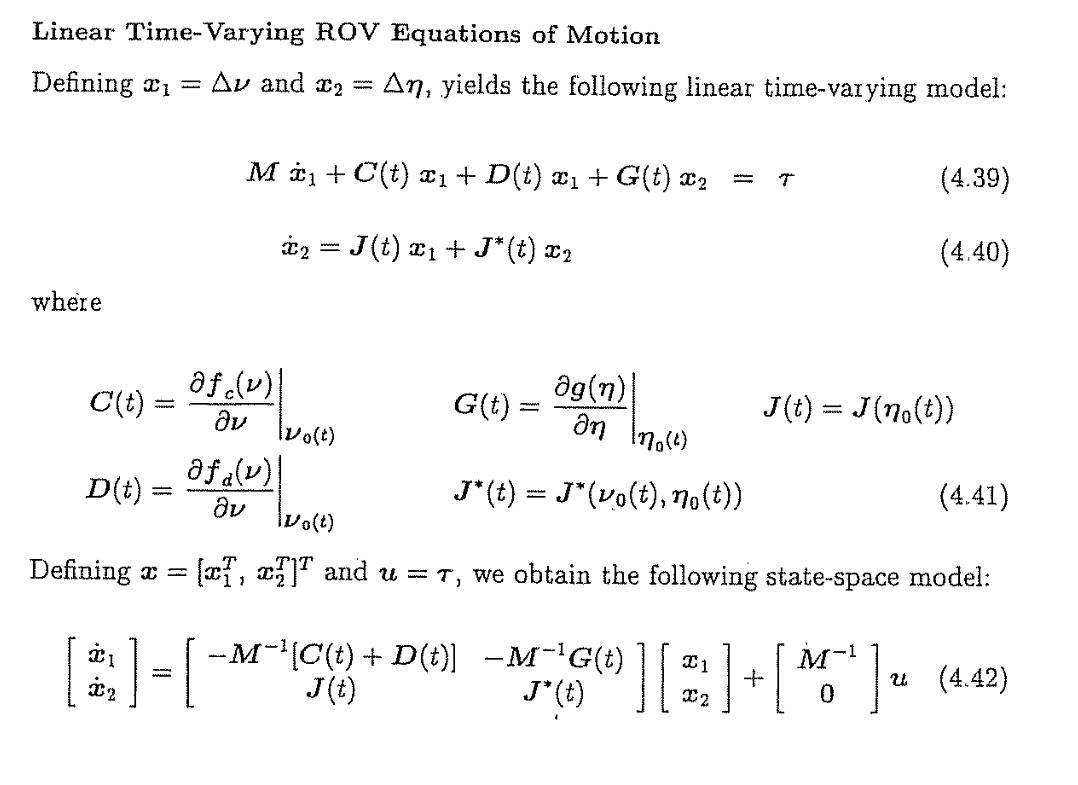

euler

    % calcules des jacobiennes
        Dj=subs(D,V,V_0);
        Dj = jacobian(Dj*V_0,V_0)
        
        Cj=subs(C,V,V_0);
        Cj = jacobian(Cj*V_0,V_0)
        
        Gj=subs(Ge,Ne,N_0);
        Gj = jacobian(Gj,N_0)
        
   % dérivée partiel de l'équation cinématique
      Jedn=subs(Je,[n1;n2],NODN);
      Je0=subs(Je,[n1;n2],N_0);
      J10=subs(J1,[n1;n2],N_0);
      
      Jstar=[J10,zeros(3,3);
             zeros(3,3),eye(3)]
     
     Ac = [zeros(6,6),Jstar;
          -(M\ Gj),-(M\(Cj + Dj))];
%     Ac =jacobian(sime,[n1;n2;V]);
%     Ac =subs(Ac,[n1;n2;V],[N_0;V_0]);
    
    Bc = [zeros(6,8);M\Tm];
    
    Cc = jacobian([Ne;V],[n1;n2;V]);
    
    Dc = jacobian([Ne;V], U );

### Modèle réduit

%     eqr= eta==sqrt(1^2 - epsilon1^2 - epsilon2^2 - epsilon3^2)
%     stater=[n1;epsilon;V]
%     
%     E2r=[eta*eye(3)+skew(epsilon)]
%     
%    Jr=[E1,zeros(3,3);
%    zeros(3,3),(1/2)*E2r]
% 
%    Jrj=jacobian(Jr*[V],stater)
% 
%     Dj = jacobian(D*V,V)
%     Cj = jacobian(C*V,V)
%     Gj = jacobian(Gq,[n1;epsilon])
%     
%     Ac = [Jrj;
%          -(M\ Gj),-(M\(Cj + Dj))];
%     
%     Bc = [zeros(6,8);M\Tm];
%     
%     Cc = jacobian([stater],[stater]);
%     
%     Dc = jacobian([stater], U );
%    
%     
%    % Att=jacobian(reSim,[]);
%    % Btt=jacobian(reSim,U);.

#### Jacobienne pour modele non linéaire

Anq = jacobian(simq,[Nq;V]);
Bnq = jacobian(simq,[U]);
Cnq = jacobian([Nq;V],[Nq;V]);
Dnq = jacobian([Nq;V],[U]);

## Implémentation 

### Substituer les constantes du modèle du sous-marin

%% Chargement des paramètres
    cf = ConfigAUV8();

    constValues = [cf.d14 ...
                 cf.d58 ...
                 cf.a14 ...
                 cf.dz ...
                 cf.z ...
                 cf.mass ...
                 cf.volume ...
                 cf.height...
                 cf.AF ...
                 cf.I(1,:) ...
                 cf.I(2,:) ...
                 cf.I(3,:) ...
                 cf.RG ...
                 cf.RB ...
                 cf.CDL...
                 cf.CDQ...
                 cf.rho ...
                 cf.g];

% Substituer les constantes dans les équation différentielles
      simqpc=subs(simqp, constMec, constValues);
      simqc=subs(simq, constMec, constValues);
      simec=subs(sime, constMec, constValues);
      Gravity =subs(Ge, constMec, constValues);

% Substituer les constantes dans les Matrices
    Av=subs(Ac, constMec, constValues);
    Bv=subs(Bc, constMec, constValues);

    Anqv=subs(Anq, constMec, constValues);
    Bnqv=subs(Bnq, constMec, constValues);

### Linéariser au condition initials.

    % États initaux
    N0=[0;0;.2246;pi/4;0;0]
    V0=[0;0;0;0;0;0]
    
    %A0=double(subs(Av, [Ne;V], [N0;V0]));
    A0=double(subs(Av, [N_0;V_0], [N0;V0]));   
    B0=double(Bv);

## Étude

Ts=0.1;
nx = size(A0,1);
nu = size(B0,2);
M = expm([[A0 B0]*Ts; zeros(nu,nu+nx)]);
Ad = M(1:nx,1:nx);
Bd = M(1:nx,nx+1:nx+nu);
Cd = double(Cc);
Dd = double(Dc);
AUVPlant=ss(Ad,Bd,Cd,Dd,Ts);

% Création du controleur MPC.
    mpcobj =mpc(AUVPlant);

% Étude de controllabilité
    c0=ctrb(A0,B0);
    nc=rank(c0)
    
% Étude de stabilité au point d'équilibre
    poles=eig(A0)


### Générer les fonctions matlab

% Générer l'équation non linéaire (quaternion) avec perturbation pour
% simulation

    matlabFunction(transpose(simqpc),'File','simulink/auv_plant/script/AUVQuatPerturbedSimFcn',...
       'Vars',{[Nq;V],F_ext,U});
   
   
%    matlabFunction(transpose(simqp),'File','simulink/auv_plant/script/AUVQuatPerturbedNoConstSimFcn',...
%        'Vars',{constMec.',[Nq;V],F_ext,U});
   
% Générer l'équation non linéaire (quaternion) sans perturbation pour le
% controlleur

   matlabFunction(transpose(simqc),'File','simulink/controller/script/AUVQuatSimFcn',...
       'Vars',{[Nq;V],U});
   
% % Générer l'équation non linéaire (Euler)   
%    matlabFunction(transpose(simec),'File','AUVEulerSimFcn',...
%        'Vars',{[Ne;V],F_ext,U});
%    
% % Générer les matrices jacobiennes (Euler)
%     matlabFunction(Av, Bv, Cc, Dc,'File','AUVEulJacobianMatrix',...
%         'Vars',{[N_0;V_0],U});  
    
% Générer les matrices jacobiennes (Quaternions)
    matlabFunction(Anqv, Bnqv, Cnq, Dnq,'File','simulink/controller/script/AUVQuatJacobianMatrix',...
        'Vars',{[Nq;V],U});    


## Sous-fonctions personalisées

Ici ce trouve nos fonctions personalisées

### Matrice antisymétrique

function sm=skew(u) 
% Convertie un vecteur 3x1 en une matrice antisymétrique 3x3
    sm=[0,-u(3),u(2);
        u(3), 0, -u(1);
       -u(2), u(1), 0];
end